### **Renombrar variables**

VariableNames = {...
    'SpMax_L', 'J_Dz(e)', 'nHM', 'F01[N-N]', 'F04[C-N]', 'NssssC', ...
    'nCb-', 'C%', 'nCp', 'nO', 'F03[C-N]', 'SdssC', 'HyWi_B(m)', 'LOC', ...
    'SM6_L', 'F03[C-O]', 'Me', 'Mi', 'nN-N', 'nArNO2', 'nCRX3', ...
    'SpPosA_B(p)', 'nCIR', 'B01[C-Br]', 'B03[C-Cl]', 'N-073', 'SpMax_A', ...
    'Psi_i_1d', 'B04[C-Br]', 'SdO', 'TI2_L', 'nCrt', 'C-026', 'F02[C-N]', ...
    'nHDon', 'SpMax_B(m)', 'Psi_i_A', 'nN', 'SM6_B(m)', 'nArCOOR', 'nX', ...
    'experimental_class'...
};

biodeg.Properties.VariableNames = VariableNames;

## Entrenamiento SVMs

% Definir los valores de los hiperparámetros
boxConstraint = [1, 3, 5];  
kernelFunctions = {'linear', 'gaussian', 'polynomial'};  
number_reps = 3;

% Generar todas las combinaciones de hiperparámetros
[BC, KF] = ndgrid(boxConstraint, 1:length(kernelFunctions));
combinaciones = [BC(:), KF(:)];
numCombinaciones = size(combinaciones, 1); 

% Número de folds
K = 10;

% Inicializar estructuras para almacenar modelos y métricas
svmModels = cell(K, numCombinaciones, number_reps);
metricsSVM = struct('Accuracy', zeros(K, numCombinaciones, number_reps), ...
                    'Recall', zeros(K, numCombinaciones, number_reps), ...
                    'Specificity', zeros(K, numCombinaciones, number_reps), ...
                    'Precision', zeros(K, numCombinaciones, number_reps), ...
                    'F1Score', zeros(K, numCombinaciones, number_reps));

% Definir las variables continuas a normalizar
variablesContinuas = [1, 2, 8, 12, 13, 14, 15, 17, 18, 22, 27, 28, 30, 31, 36, 37, 39];

% Entrenamiento con Cross Validation para cada combinación
for modelIdx = 1:numCombinaciones
    % Obtener los hiperparámetros de la combinación actual
    c = combinaciones(modelIdx, 1);
    kernelIdx = combinaciones(modelIdx, 2);
    kernel = kernelFunctions{kernelIdx};

    for rep = 1:number_reps
        % Nueva partición aleatoria para cada repetición
        cv = cvpartition(biodeg_copy.experimental_class, 'KFold', K, 'Stratify', true);

        for fold = 1:K
            % Dividir en entrenamiento y prueba
            trainData = biodeg_copy(training(cv, fold), :);
            testData = biodeg_copy(test(cv, fold), :);

            % Calcular media y desviación estándar en el conjunto de entrenamiento
            media = mean(trainData{:, variablesContinuas});
            desviacion = std(trainData{:, variablesContinuas});

            % Normalizar conjuntos
            trainData{:, variablesContinuas} = (trainData{:, variablesContinuas} - media) ./ desviacion;
            testData{:, variablesContinuas} = (testData{:, variablesContinuas} - media) ./ desviacion;

            % Extraer datos de entrenamiento y prueba
            X_train = trainData{:, 1:41};
            Y_train = trainData{:, 42};
            X_test = testData{:, 1:41};
            Y_test = testData{:, 42};

            % Entrenar modelo SVM
            modeloSVM = fitcsvm(X_train, Y_train, ...
                'BoxConstraint', c, ...
                'KernelFunction', kernel);

            % Hacer predicciones
            predictions = predict(modeloSVM, X_test);

            % Matriz de confusión
            confusionMat = confusionmat(Y_test, predictions, 'Order', {'RB', 'NRB'});
            
            % Calcular métricas usando performanceIndexes
            [recall, specificity, precision, ~, accuracy, f1score] = performanceIndexes(confusionMat, 1);  % 'RB' como clase positiva
            
            % Almacenar métricas
            metricsSVM.Accuracy(fold, modelIdx, rep)    = accuracy;
            metricsSVM.Recall(fold, modelIdx, rep)      = recall;
            metricsSVM.Specificity(fold, modelIdx, rep) = specificity;
            metricsSVM.Precision(fold, modelIdx, rep)   = precision;
            metricsSVM.F1Score(fold, modelIdx, rep)     = f1score;

            svmModels{fold, modelIdx, rep} = modeloSVM;
        end
    end
end

% ------------------------ MÉTRICAS PROMEDIO Y STD ------------------------

% Cálculo de métricas promediando sobre folds y repeticiones
Mean_RecallSVM_final     = squeeze(mean(mean(metricsSVM.Recall, 1), 3));
Std_RecallSVM_final      = squeeze(std(reshape(metricsSVM.Recall, K*number_reps, []), 0, 1));

Mean_SpecificitySVM_final           = squeeze(mean(mean(metricsSVM.Specificity, 1), 3));
Std_SpecificitySVM_final            = squeeze(std(reshape(metricsSVM.Specificity, K*number_reps, []), 0, 1));

Mean_PrecisionSVM_final  = squeeze(mean(mean(metricsSVM.Precision, 1), 3));
Std_PrecisionSVM_final   = squeeze(std(reshape(metricsSVM.Precision, K*number_reps, []), 0, 1));

Mean_ACCSVM_final        = squeeze(mean(mean(metricsSVM.Accuracy, 1), 3));
Std_ACCSVM_final         = squeeze(std(reshape(metricsSVM.Accuracy, K*number_reps, []), 0, 1));

Mean_F1ScoreSVM_final    = squeeze(mean(mean(metricsSVM.F1Score, 1), 3));
Std_F1ScoreSVM_final     = squeeze(std(reshape(metricsSVM.F1Score, K*number_reps, []), 0, 1));

function mostrarResumenSVM(combinaciones, kernelFunctions, ...
    Mean_ACCSVM, Std_ACCSVM, ...
    Mean_RecallSVM, Std_RecallSVM, ...
    Mean_PrecisionSVM, Std_PrecisionSVM, ...
    Mean_SpecificitySVM_final, Std_SpecificitySVM_final, ...
    Mean_F1ScoreSVM, Std_F1ScoreSVM)

    numCombinaciones = size(combinaciones, 1);

    modelo = strings(numCombinaciones, 1);
    kernel = strings(numCombinaciones, 1);
    BC = zeros(numCombinaciones, 1);

    Accuracy = zeros(numCombinaciones, 1);
    Accuracy_std = zeros(numCombinaciones, 1);
    Recall = zeros(numCombinaciones, 1);
    Recall_std = zeros(numCombinaciones, 1);
    Precision = zeros(numCombinaciones, 1);
    Precision_std = zeros(numCombinaciones, 1);
    Specificity = zeros(numCombinaciones, 1);
    Specificity_std = zeros(numCombinaciones, 1);
    F1 = zeros(numCombinaciones, 1);
    F1_std = zeros(numCombinaciones, 1);

    for i = 1:numCombinaciones
        BC(i) = combinaciones(i, 1);
        kernel(i) = kernelFunctions{combinaciones(i, 2)};
        modelo(i) = sprintf("SVM %d", i);

        Accuracy(i) = Mean_ACCSVM(i);
        Accuracy_std(i) = Std_ACCSVM(i);
        Recall(i) = Mean_RecallSVM(i);
        Recall_std(i) = Std_RecallSVM(i);
        Precision(i) = Mean_PrecisionSVM(i);
        Precision_std(i) = Std_PrecisionSVM(i);
        Specificity(i) = Mean_SpecificitySVM_final(i);
        Specificity_std(i) = Std_SpecificitySVM_final(i);
        F1(i) = Mean_F1ScoreSVM(i);
        F1_std(i) = Std_F1ScoreSVM(i);
    end

    tabla = table(modelo, BC, kernel, ...
        Accuracy, Accuracy_std, ...
        Recall, Recall_std, ...
        Precision, Precision_std, ...
        Specificity, Specificity_std, ...
        F1, F1_std);

    disp(tabla);
end

mostrarResumenSVM(combinaciones, kernelFunctions, ...
    Mean_ACCSVM_final, Std_ACCSVM_final, ...
    Mean_RecallSVM_final, Std_RecallSVM_final, ...
    Mean_PrecisionSVM_final, Std_PrecisionSVM_final, ...
    Mean_SpecificitySVM_final, Std_SpecificitySVM_final, ...
    Mean_F1ScoreSVM_final, Std_F1ScoreSVM_final);

    modelo     BC       kernel       Accuracy    Accuracy_std    Recall     Recall_std    Precision    Precision_std    Specificity    Specificity_std      F1        F1_std 
    _______    __    ____________    ________    ____________    _______    __________    _________    _____________    ___________    _______________    _______    ________

    "SVM 1"    1     "linear"        0.86821       0.030355      0.78251     0.062037       0.8221       0.056913         0.91182         0.031097        0.79997     0.04773
    "SVM 2"    3     "linear"      

% Almacenar las métricas para la primera repetición

metricsSVM_1 = struct('Accuracy', metricsSVM.Accuracy(:,:,1), ...
                    'Recall', metricsSVM.Recall(:,:,1), ...
                    'Specificity', metricsSVM.Specificity(:,:,1), ...
                    'Precision', metricsSVM.Precision(:,:,1), ...
                    'F1Score', metricsSVM.F1Score(:,:,1));


Test de Kruskal-Wallis para Accuracy


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


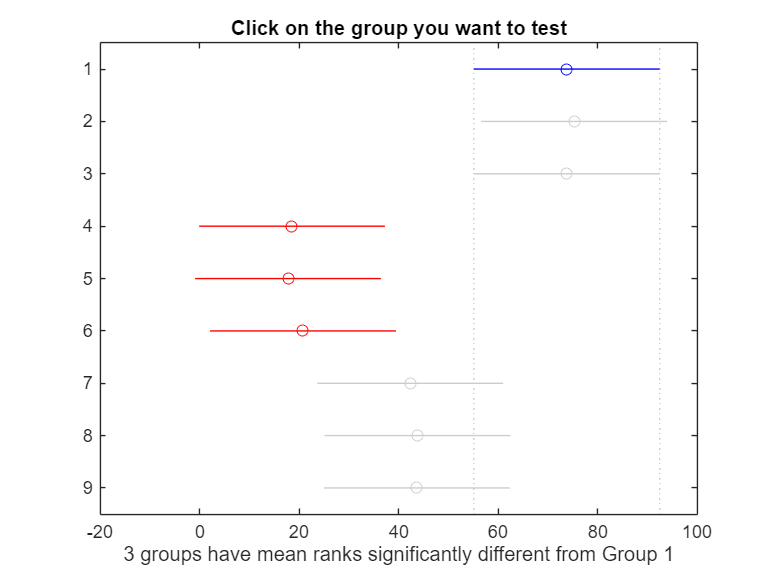

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI      PValue  
    ______    ______    ________    ______    ________    __________

      1         2       -38.832       -1.5     35.832              1
      1         3       -37.332          0     37.332              1
      1         4        17.868       55.2     92.532     8.1983e-05
      1         5        18.668         56     93.332     5.8381e-05
      1         6        15.668         53     90.332     0.00020375
      1         7       -5.8818      31.45     68.782        0.25473
      1         8       -7.3318         30     67.332        0.36708
      1         9       -7.2318       30.1     67.432        0.35811
      2         3       -35.832        1.5     38.832              1
      2         4        19.368     


Test de Kruskal-Wallis para Recall


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


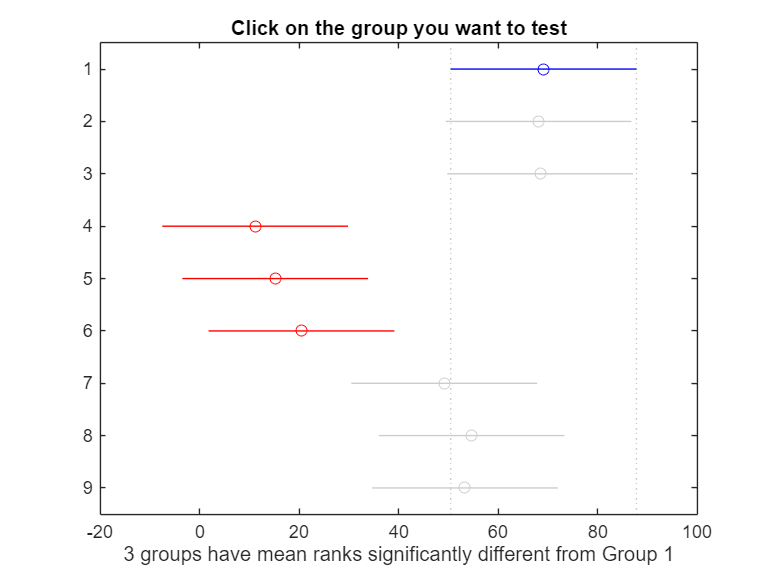

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI      PValue  
    ______    ______    ________    ______    ________    __________

      1         2        -36.32          1       38.32             1
      1         3        -36.62        0.7       38.02             1
      1         4         20.63      57.95       95.27    2.4841e-05
      1         5         16.58       53.9       91.22    0.00014001
      1         6         11.33      48.65       85.97     0.0011087
      1         7        -17.37      19.95       57.27             1
      1         8        -22.87      14.45       51.77             1
      1         9        -21.52       15.8       53.12             1
      2         3        -37.62       -0.3       37.02             1
      2         4         19.63     


Test de Kruskal-Wallis para Specificity


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


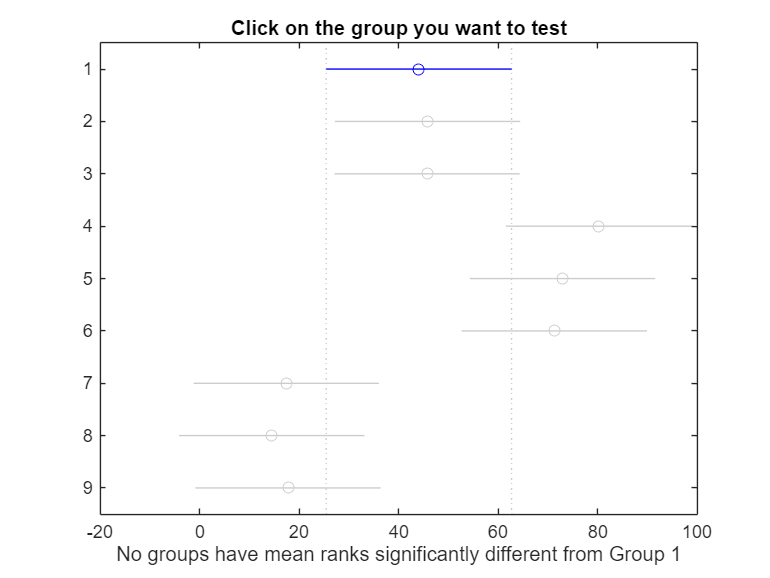

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI      PValue  
    ______    ______    ________    ______    ________    __________

      1         2       -38.984      -1.75     35.484              1
      1         3       -38.884      -1.65     35.584              1
      1         4       -73.334      -36.1      1.134       0.069765
      1         5       -66.084     -28.85      8.384        0.47685
      1         6       -64.434      -27.2     10.034        0.70277
      1         7       -10.584      26.65     63.884        0.79654
      1         8        -7.684      29.55     66.784        0.40228
      1         9       -10.934       26.3     63.534        0.86171
      2         3       -37.134        0.1     37.334              1
      2         4       -71.584     


Test de Kruskal-Wallis para Precision


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


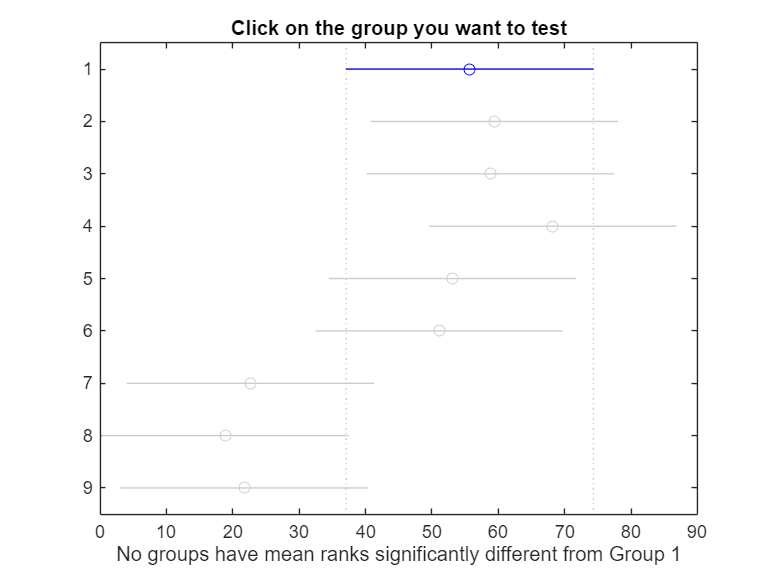

    Grupo1    Grupo2    Lower_CI    Diff     Upper_CI      PValue  
    ______    ______    ________    _____    ________    __________

      1         2        -40.988     -3.7     33.588              1
      1         3        -40.388     -3.1     34.188              1
      1         4        -49.788    -12.5     24.788              1
      1         5        -34.688      2.6     39.888              1
      1         6        -32.688      4.6     41.888              1
      1         7        -4.2381    33.05     70.338         0.1657
      1         8       -0.43807    36.85     74.138       0.056916
      1         9        -3.2881       34     71.288        0.12803
      2         3        -36.688      0.6     37.888              1
      2         4        -46.088     -8.8     2


Test de Kruskal-Wallis para F1Score


P-valor: 0.0000


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


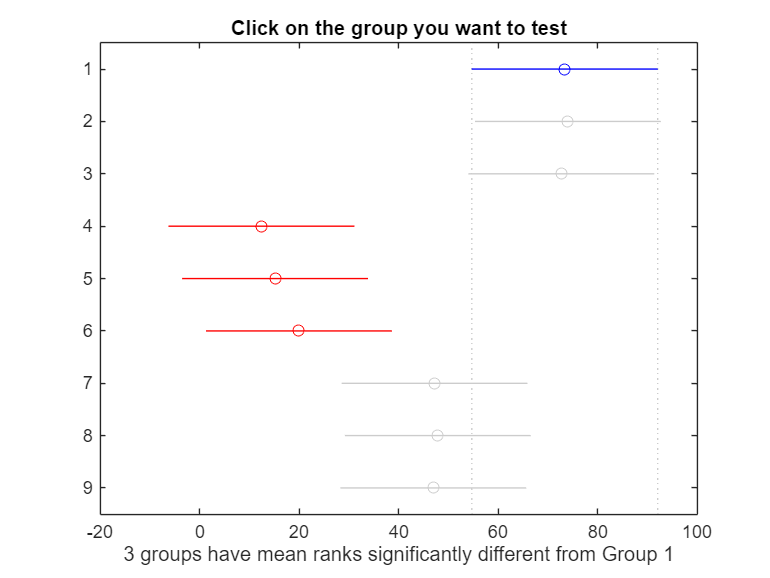

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI      PValue  
    ______    ______    ________    ______    ________    __________

      1         2       -37.998      -0.65     36.698              1
      1         3       -36.648        0.7     38.048              1
      1         4        23.602      60.95     98.298     6.5362e-06
      1         5        20.852       58.2     95.548     2.2668e-05
      1         6        16.052       53.4     90.748     0.00017473
      1         7       -11.198      26.15     63.498        0.90696
      1         8       -11.848       25.5     62.848              1
      1         9       -10.948       26.4     63.748        0.85795
      2         3       -35.998       1.35     38.698              1
      2         4        24.252     

% Lista de métricas a evaluar
metricNames = {'Accuracy', 'Recall', 'Specificity', 'Precision', 'F1Score'};

% Aplicar Kruskal-Wallis para cada métrica
for m = 1:numel(metricNames)
    metricName = metricNames{m};
    
    % Extraer la métrica de los modelos de Árbol de Decisión
    metricData = metricsSVM_1.(metricName); 

    % Aplicamos el test de Kruskal-Wallis
    [p,~,stats] = kruskalwallis(metricData, [], 'off');
    
    % Mostramos el resultado del test
    fprintf('\nTest de Kruskal-Wallis para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    % Si hay diferencias significativas, realizamos comparaciones múltiples
    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        
        % Comparaciones múltiples usando multcompare
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni'); 
        
        % Mostrar tabla de comparaciones múltiples
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

% Los mejores modelos son los lineales y los polinomiales, dado que las
% diferencias entre estos grupos no son significativas nos quedamos con el
% mas simple de los modelos lienales (el 1)

metricsSVM_R1_M1 = struct('Accuracy', metricsSVM_1.Accuracy(:,1), ...
                    'Recall', metricsSVM_1.Recall(:,1), ...
                    'Specificity', metricsSVM_1.Specificity(:,1), ...
                    'Precision', metricsSVM_1.Precision(:,1), ...
                    'F1Score', metricsSVM_1.F1Score(:,1));


Test de Kruskal-Wallis para Accuracy


P-valor: 0.0139


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


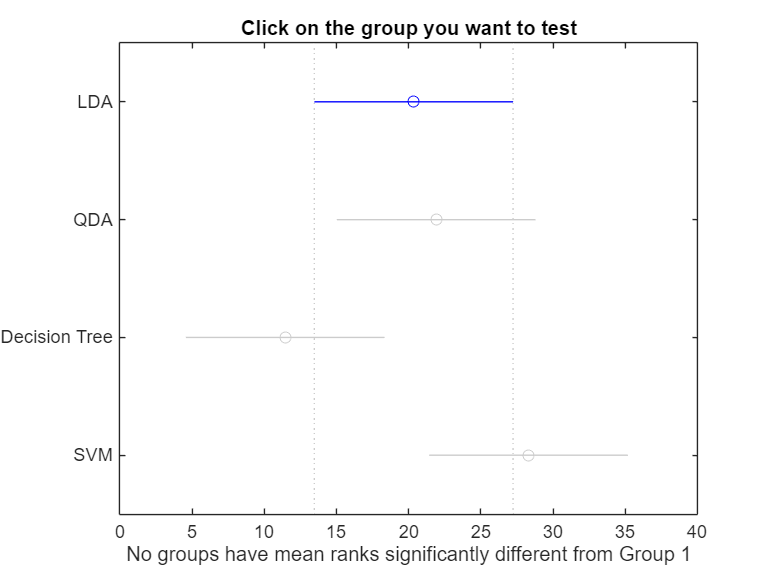

    Grupo1    Grupo2    Lower_CI     Diff     Upper_CI     PValue  
    ______    ______    ________    ______    ________    _________

      1         2       -15.316      -1.55     12.216             1
      1         3        -4.866        8.9     22.666       0.52839
      1         4       -21.716      -7.95      5.816       0.76561
      2         3        -3.316      10.45     24.216       0.27122
      2         4       -20.166       -6.4      7.366             1
      3         4       -30.616     -16.85     -3.084     0.0074451




Test de Kruskal-Wallis para Recall


P-valor: 0.0450


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


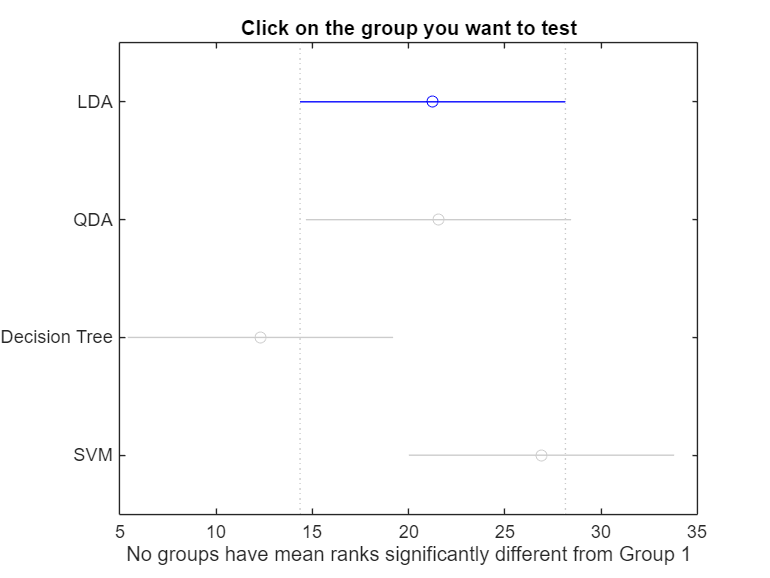

    Grupo1    Grupo2    Lower_CI    Diff     Upper_CI     PValue 
    ______    ______    ________    _____    ________    ________

      1         2       -14.084      -0.3      13.484           1
      1         3       -4.8341      8.95      22.734     0.52025
      1         4       -19.434     -5.65      8.1341           1
      2         3       -4.5341      9.25      23.034     0.45992
      2         4       -19.134     -5.35      8.4341           1
      3         4       -28.384     -14.6    -0.81591    0.031196




Test de Kruskal-Wallis para Specificity


P-valor: 0.4253


No se encontraron diferencias significativas entre los modelos para Specificity.



Test de Kruskal-Wallis para Precision


P-valor: 0.2269


No se encontraron diferencias significativas entre los modelos para Precision.



Test de Kruskal-Wallis para F1Score


P-valor: 0.0052


Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...


Note: Intervals can be used for testing but are not simultaneous confidence intervals.


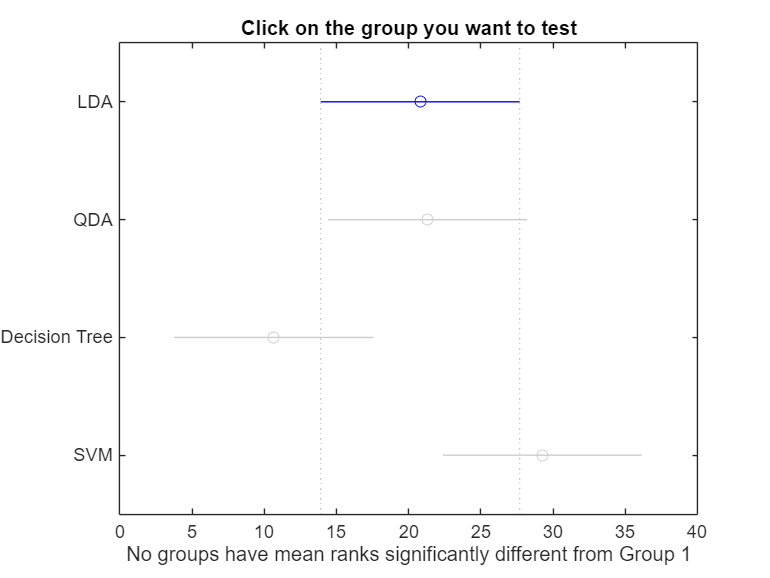

    Grupo1    Grupo2    Lower_CI    Diff     Upper_CI     PValue  
    ______    ______    ________    _____    ________    _________

      1         2       -14.289      -0.5     13.289             1
      1         3       -3.6386     10.15     23.939       0.31278
      1         4       -22.239     -8.45     5.3386       0.63554
      2         3       -3.1386     10.65     24.439       0.24946
      2         4       -21.739     -7.95     5.8386       0.76938
      3         4       -32.389     -18.6    -4.8114     0.0022349



% Lista de métricas a evaluar
metricNames = {'Accuracy', 'Recall', 'Specificity', 'Precision', 'F1Score'};

% Comparar entre Árbol Sencillo, LDA y QDA
for m = 1:numel(metricNames)
    metricName = metricNames{m};

    % Extraer valores de cada modelo
    lda_values = metricsLDA.(metricName);
    qda_values = qdametrics.(metricName);
    arbol_values = metricsArbol.(metricName)(:, 1); % Árbol más sencillo
    svm_values = metricsSVM_R1_M1.(metricName);

    % Concatenar todas las métricas en una sola variable
    combined_values = [lda_values; qda_values; arbol_values; svm_values];

    % Crear etiquetas de grupo (1 = LDA, 2 = QDA, 3 = Árbol Sencillo, 4 = SVM sencillo)
    numFolds = size(lda_values, 1);
    group_labels = [ones(numFolds, 1); 2 * ones(numFolds, 1); 3 * ones(numFolds, 1); 4*ones(numFolds, 1)];

    % Aplicamos el test de Kruskal-Wallis
    [p,~,stats] = kruskalwallis(combined_values, group_labels, 'off');

    % Mostramos el resultado del test
    fprintf('\nTest de Kruskal-Wallis para %s\n', metricName);
    fprintf('P-valor: %.4f\n', p);

    % Si hay diferencias significativas, realizamos comparaciones múltiples
    if p < 0.05
        fprintf('Se encontraron diferencias significativas entre los modelos. Realizando comparaciones múltiples...\n');
        
        % Comparaciones múltiples usando multcompare
        figure;
        title(sprintf('Comparaciones múltiples para %s', metricName));
        [c,~,~,gnames] = multcompare(stats, 'CType', 'bonferroni');
        ax = gca; % obtiene el axis actual
        ax.YTickLabel = {'SVM', 'Decision Tree', 'QDA', 'LDA'};
        
        % Mostrar tabla de comparaciones múltiples
        disp(array2table(c, 'VariableNames', {'Grupo1', 'Grupo2', 'Lower_CI', 'Diff', 'Upper_CI', 'PValue'}));
    else
        fprintf('No se encontraron diferencias significativas entre los modelos para %s.\n', metricName);
    end
end

Como se puede observar hay diferencias significativas entre el SVM y el árbol de decisión, obteniendo el SVM mejor resultado. Aún así no existen difrencias significativas entre el SVM y el discriminante lineal de fisher, por lo que nos quedamos con este último por ser más sencillo.